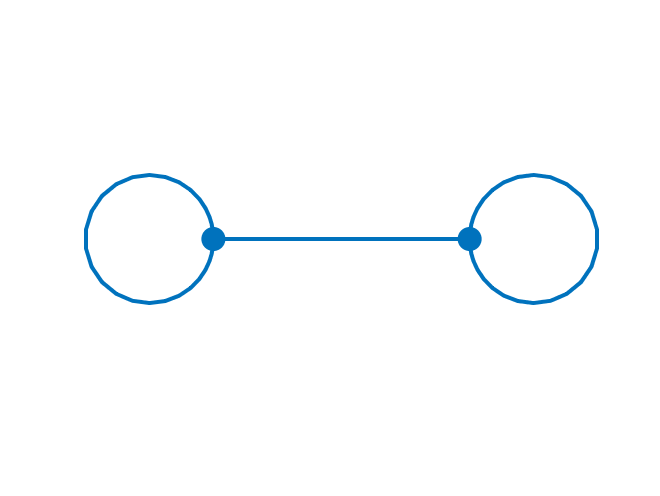

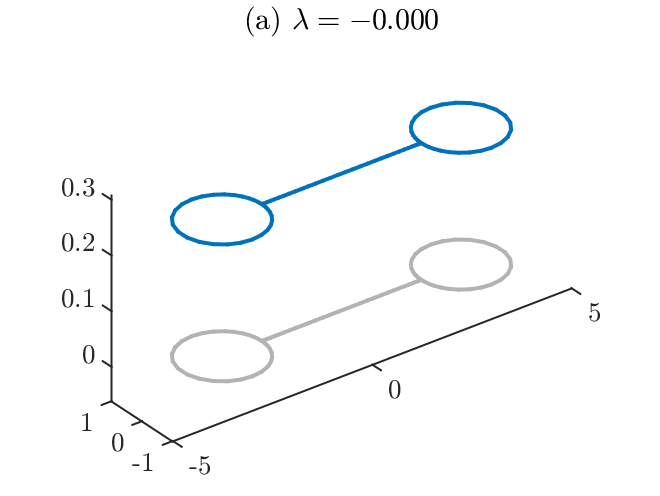

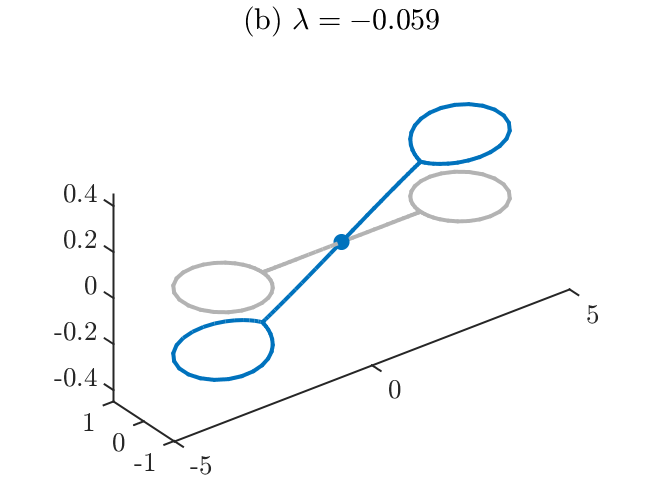

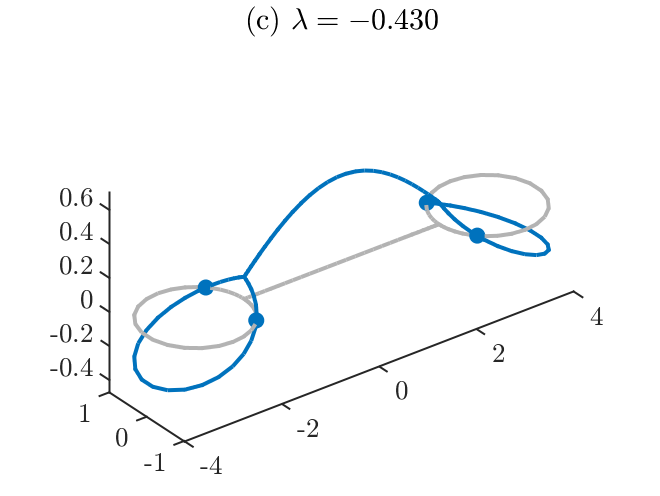

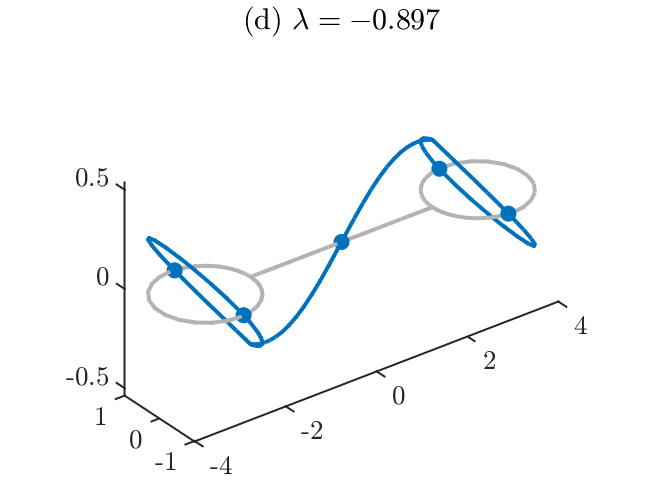

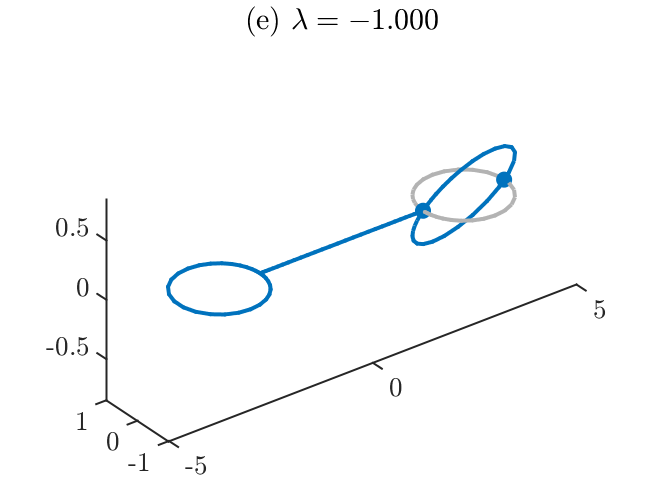

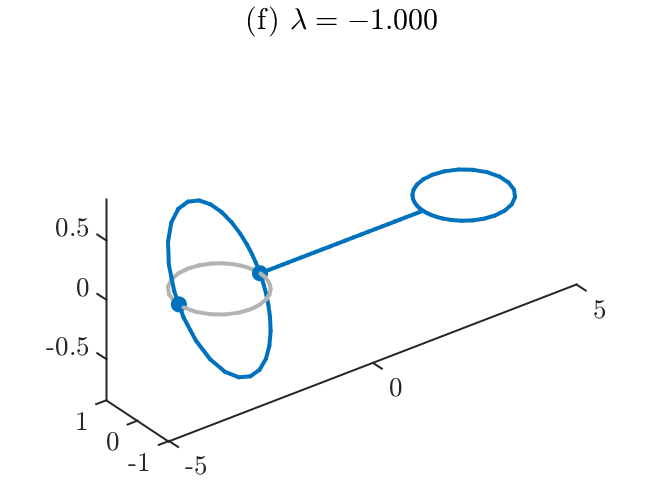

Saved to directory data/dumbbell/081.
Run number is 81.


tag='dumbbell';
Phi = quantumGraphFromTemplate('dumbbell','discretization','Chebyshev','nx',32);

nToPlot=4;
nDoubles=1;
dataDir=eigenfunctionsSaveData(Phi,tag,nToPlot,nDoubles);

fcns = saveNLSFunctionsGraph(dataDir,Phi);

options=continuerSet([],'LambdaThresh',-1,'NThresh',6,'plotFlag',false);
eigNumber=1;
branch1 =continueFromEig(dataDir,eigNumber,options);

N threshold crossed.
Branch number 1.
Data saved to directory data/dumbbell/081/branch001.
Branching Bifurcation at solution number 5.
Branching Bifurcation at solution number 8.
Branching Bifurcation at solution number 11.
Branching Bifurcation at solution number 13.


branch2 =continueFromBranchPoint(dataDir,branch1,1,1,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data/dumbbell/081/branch002.
No branching bifurcations found.


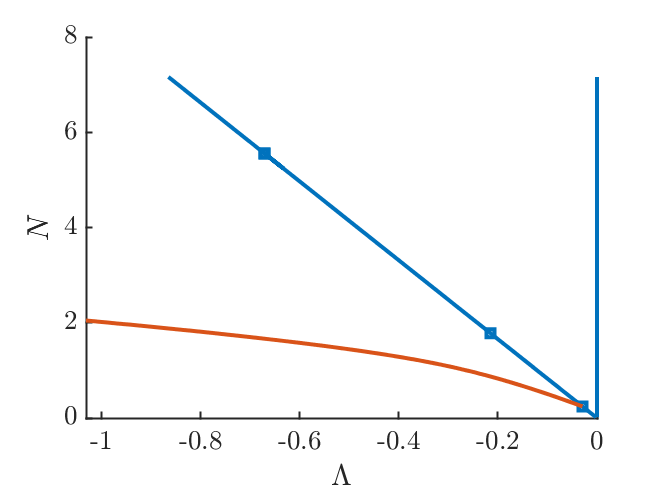

bifurcationDiagram(dataDir)

branch3 =continueFromBranchPoint(dataDir,branch1,2,1,options);

Lambda threshold crossed.
Branch number 3.
Data saved to directory data/dumbbell/081/branch003.
Branching Bifurcation at solution number 17.


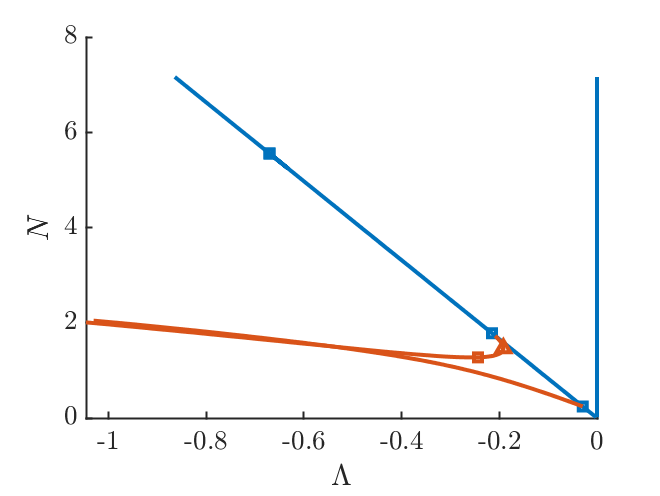

bifurcationDiagram(dataDir)

branch4 =continueFromBranchPoint(dataDir,branch1,2,-1,options);

Lambda threshold crossed.
Branch number 4.
Data saved to directory data/dumbbell/081/branch004.
No branching bifurcations found.


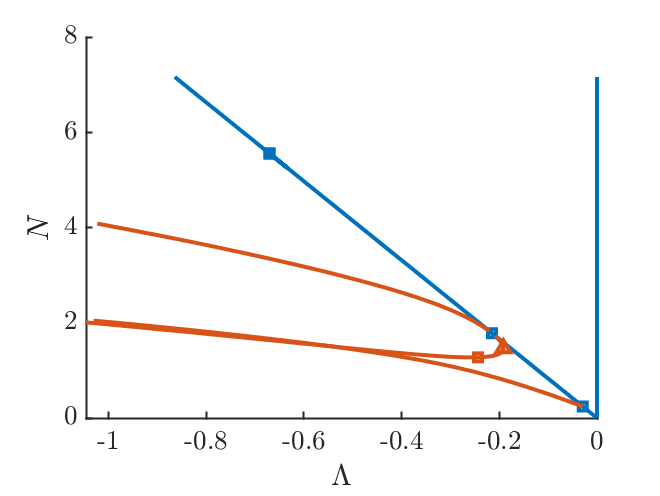

bifurcationDiagram(dataDir)

branch5 =continueFromBranchPoint(dataDir,branch3,1,1,options);
bifurcationDiagram(dataDir)

Lambda0=-4;
edges=[1 2];
signs=[1 1];
filenumber=saveHighFrequencyStandingWave(dataDir,Lambda0,edges,signs);

options=continuerSet(options,'LambdaThresh',-4.1,'NThresh',9);
branch6 =continueFromSaved(dataDir,filenumber,-1,options);
bifurcationDiagram(dataDir)

NExtra=2; LambdaExtra=2;
branch7 =continueFromEnd(dataDir,branch1,'last',NExtra,LambdaExtra,options);
bifurcationDiagram(dataDir)

rmBranch(dataDir,'last')
bifurcationDiagram(dataDir)

rmBranch(dataDir,branch5)
bifurcationDiagram(dataDir)

plotSolution(dataDir,branch3,15)

plotSolution(dataDir,branch6,'last')
